clc
clear all

% 0 = only negative pressure values
% 1 = only positive pressure values
% 2 = both pos&neg pressure values
positive_values = 2;

length_signal = 100;
start_signal = 200;

%load("C:\Users\emile\Downloads\pressure.mat")
%load("C:\Users\emile\Downloads\DOA.mat")

load("opt_truncated_mat_files\DOA.mat")
load("opt_truncated_mat_files\pressure.mat")

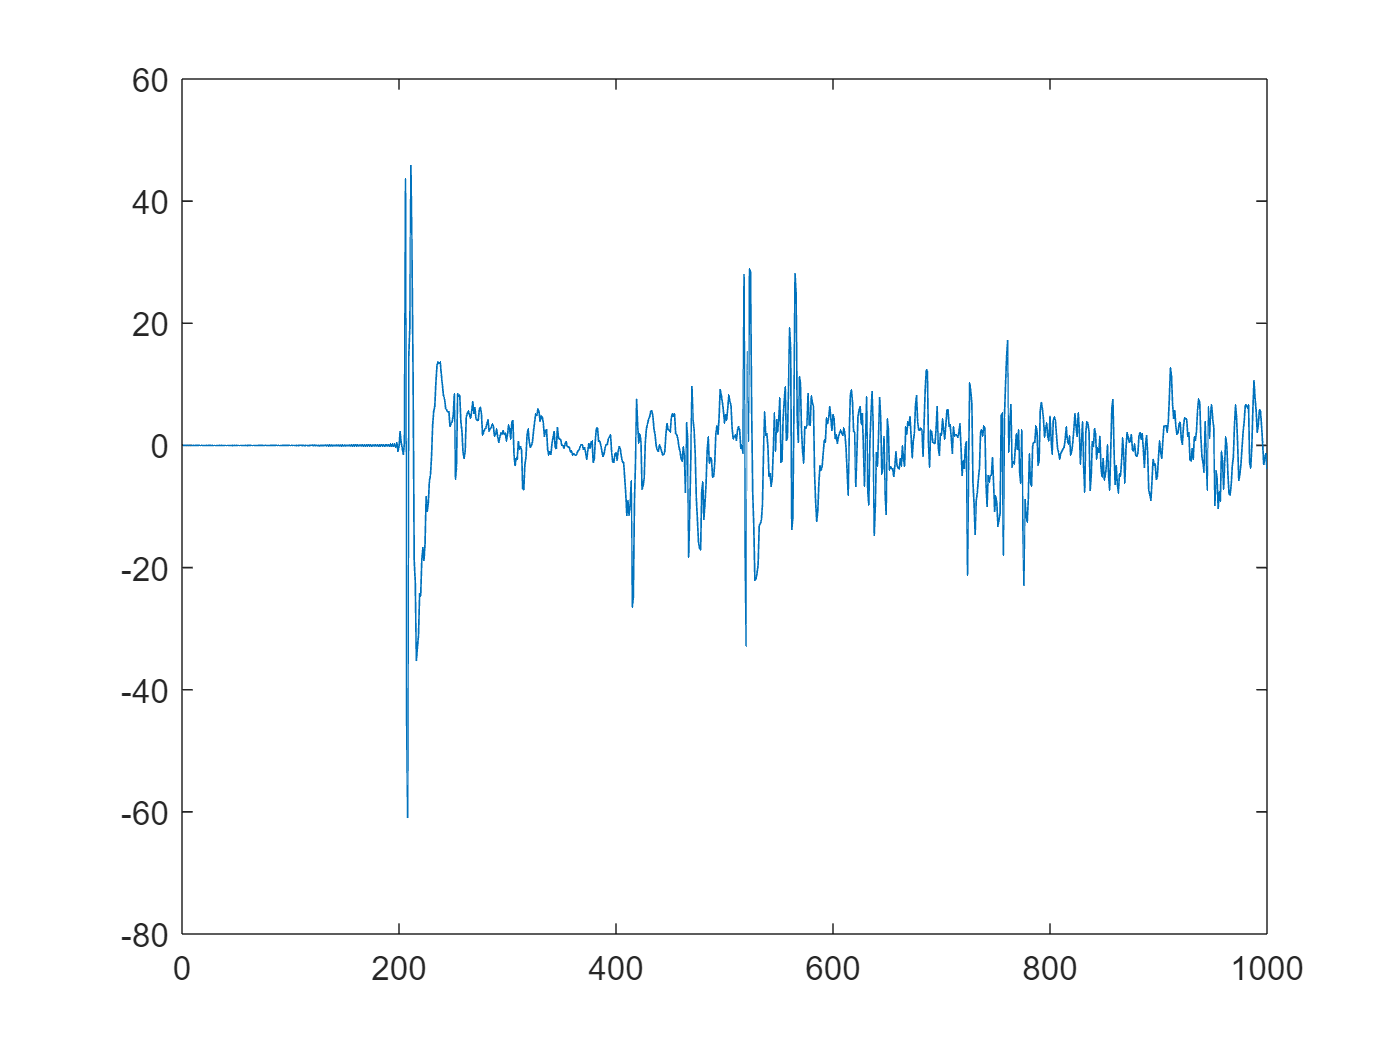

plot(P{1,1}(1:1000))

end_signal = start_signal + length_signal;

DOA1 = DOA{1,1}(start_signal:end_signal,:);
P1 = P{1,1}(start_signal:end_signal);
DOA3 = DOA{3,1}(start_signal:end_signal,:);
P3 = P{3,1}(start_signal:end_signal);

if positive_values == 1
    P1(P1 < 0) = 0;
    P3(P3 < 0) = 0;
elseif positive_values == 0
    P1(P1 > 0) = 0;
    P3(P3 > 0) = 0;
    P1 = abs(P1);
    P3 = abs(P3);
elseif positive_values == 2
    P1 = abs(P1);
    P3 = abs(P3);
end

norm(P1,1)

ans = 916.5986

norm(P3,1)

ans = 1.0211e+03

clear DOA
clear P

number_of_discrete_positions = 12;
number_of_speakers = 2;

size_matrix = length(P1);
cost = zeros(size_matrix);

speed_of_sound = 343/48000;

% Optimal transport for measurement 1 and 3
% Cost matrix
for i=1:size_matrix
    for j=1:size_matrix
        cost(j,i) = power(norm(DOA1(i,1:3)*(speed_of_sound*i + speed_of_sound*start_signal) - (DOA3(j,1:3)*(speed_of_sound*j + speed_of_sound*start_signal))), 2);
    end
end

% Partial optimal transport matrix extend

distance_between_measurements = 0.4; % Distance between measurement 1 and 3 -> 40cm
epsilon = 1.05*power(norm(distance_between_measurements), 2);% increasing to 1.1-1.5 provide tolerance for imprecision

column = epsilon*ones(size_matrix,1); % Maybe infinity will cause an error
row = transpose(column);

cost_extended = [cost column; row Inf];

% See namegiving in paper RIR interpolation
a = P1;
b = P3;
a(a<0) = 0;
b(b<0) = 0;

% Check which solver is selected
cvx_solver

   Name     Status             Version   Location
--------------------------------------------------------
   SDPT3                       4.0       {cvx}\sdpt3
   SeDuMi   selected,default   1.3.4     {cvx}\sedumi



% Select sedumi solver if not yet selected
cvx_solver sedumi

% Save preferences for solver
cvx_save_prefs

Saving prefs...done.


% Partial Optimal Transport

cvx_begin
    cvx_precision low
    variable T_bar(size_matrix+1,size_matrix+1) nonnegative
    variable sig
    to_minimize = cvx(zeros(size_matrix+1,size_matrix+1));

    %T_bar(size_matrix+1,size_matrix+1) = 0;

    a_bar = [a ; norm(b,1) - sig];
    b_bar = [b ; norm(a,1) - sig];

    for i=1:size_matrix
        for j=1:size_matrix
            if i ~= size_matrix+1 && j ~= size_matrix+1
                to_minimize(i,j) = T_bar(i,j)*cost_extended(i,j);
            else
                to_minimize(i,j) = 0;
            end
        end
    end

    minimize( sum(sum(to_minimize)))
    subject to
        sig >= 0
        sig <= norm(a,1)
        sig <= norm(b,1)
        T_bar*ones(size_matrix+1, 1) == a_bar
        transpose(T_bar)*ones(size_matrix+1, 1) == b_bar
        sum(sum(T_bar(1:size_matrix,1:size_matrix))) == sig
        T_bar(size_matrix+1,size_matrix+1) == 0

        for i=1:size_matrix+1
            for j=1:size_matrix+1
                T_bar(i,j) >= 0
            end
        end
cvx_end

 
Calling SeDuMi 1.3.4: 21016 variables, 10404 equality constraints
   For improved efficiency, SeDuMi is solving the dual problem.
------------------------------------------------------------
SeDuMi 1.3.4 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, Adaptive Step-Differentiation, theta = 0.250, beta = 0.500
Split 205 free variables
eqs m = 10404, order n = 21222, dim = 21222, blocks = 1
nnz(A) = 20809 + 62020, nnz(ADA) = 10404, nnz(L) = 10404
Handling 410 + 0 dense columns.
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            2.76E+00 0.000
  1 :   8.10E+04 6.81E-01 0.000 0.2467 0.9000 0.9000  -0.50  1  1  3.2E+00
  2 :   3.80E+04 3.04E-01 0.000 0.4469 0.9000 0.9000   2.26  1  1  8.1E-01
  3 :   1.47E+04 8.66E-02 0.000 0.2847 0.9000 0.9000   2.80  1  1  1.1E-01
  4 :   8.55E+03 3.57E-02 0.000 0.4118 0.9000 0.9000   1.56  1  1  4.0E-02
  5 :   7.62E+03 3.10E-02 0.000 0.8676 0.9000 0.9000   1.02  1  1  3.4E-02
  6 :   7.06E

disp(sig)

   52.0464



T_ = T_bar;

T_bar = T_;
% moeten we dit wel doen, verliezen we dan niet gwn accuratie
for i=1:size_matrix+1
    for j=1:size_matrix+1
        if T_bar(i,j) < 1e-5
            T_bar(i,j) = 0;
        end
    end
end

norm(T_bar)

ans = 163.0067

if positive_values == 1
    save("opt_truncated_mat_files\Tbar_positive.mat", "T_bar")
elseif positive_values == 0
    save("opt_truncated_mat_files\Tbar_negative.mat", "T_bar")
elseif positive_values == 2
    save("opt_truncated_mat_files\Tbar.mat", "T_bar")
end